## Visualization - Determining robot paths

This live script goes through the process of visualizing the path of the neato robot theoretically and experimentally. We also analyze the error between these two sets. Requires the input of a valid datafile, probably made using the "collectDataset" script used in QEA.

% load a file and process a bit, removing some bad samples at the 
% very beginning
load 'mapping2.mat'
dataset(1:28,:) = [];
pos_left = dataset(:, 2);
pos_right = dataset(:, 3);
pos_times = dataset(:, 1);

% distance between wheel constant
d = 0.254;

% calculate velocities (ang and lin)
vel_data = diff(dataset);
vel_left = vel_data(:, 2) ./ mean(vel_data(:, 1));
vel_right = vel_data(:, 3) ./ mean(vel_data(:, 1));
vel_times = vel_data(:, 1);
vel = (vel_left + vel_right) ./ 2;
w_exp = (vel_left - vel_right) ./ d;

% compile data for experimental position data
pos_exp = zeros(size(pos_left,1), 3);
that_exp = zeros(size(pos_left,1), 2);
for i = 2:1:size(pos_times, 1) - 2 
    % find the tangent using cos and sin by considerin the unit circle
    that_exp(i, 1) = cos(pos_exp(i - 1, 3));
    that_exp(i, 2) = sin(pos_exp(i - 1, 3));
    % determine the position vector from what we figured out in class
    pos_exp(i, :) = [(vel(i) * vel_times(i) * that_exp(i, 1)) + pos_exp(i - 1, 1) (vel(i) * vel_times(i) * that_exp(i, 2)) + pos_exp(i - 1, 2)...
                     (w_exp(i) * vel_times(i)) + pos_exp(i - 1, 3)];
    % determine error at this point by finding distance from point at this
    % sample index of theoretical to this point experimentally.
end
% the last couple data points seem to frequently get messed up
pos_exp = pos_exp(1:end-2, :);

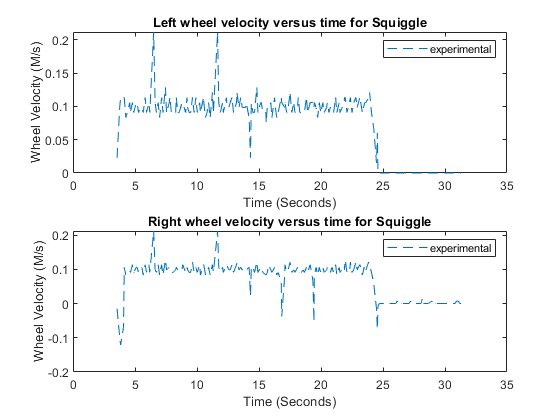

% Plot wheel velocities
figure()

subplot(2,1,1);
plot(pos_times(1:end-1), vel_left, '--')
title('Left wheel velocity versus time for Squiggle');
legend('experimental')
xlabel('Time (Seconds)');
ylabel('Wheel Velocity (M/s)');

subplot(2,1,2);
plot(pos_times(1:end-1), vel_right, '--')
title('Right wheel velocity versus time for Squiggle');
legend('experimental')
xlabel('Time (Seconds)');
ylabel('Wheel Velocity (M/s)');

print('plots/WheelVelocities', '-dpng', '-r300');

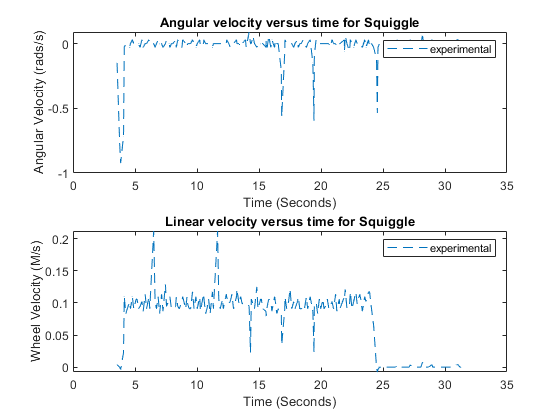

% Plot linear and angular speed versus time
figure()
subplot(2,1,1);
plot(pos_times(1:end-1), -w_exp, '--')
title('Angular velocity versus time for Squiggle');
legend('experimental')
xlabel('Time (Seconds)');
ylabel('Angular Velocity (rads/s)');

subplot(2,1,2);
plot(pos_times(1:end-1), vel, '--')
title('Linear velocity versus time for Squiggle');
legend('experimental')
xlabel('Time (Seconds)');
ylabel('Wheel Velocity (M/s)');
print('plots/VAndWVsTime', '-dpng', '-r300');

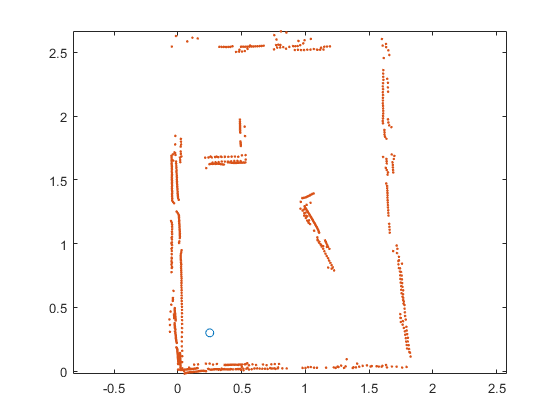

Undefined function or variable 'rmoutliers'.

Error in RANSAC_map>RANSAC (line 83)
inliers = rmoutliers(bestInliers, 'median');

Error in RANSAC_map (line 31)
    [line, outliers, inliers] = RANSAC([x y],5/100,20);

% bucket position
cx = 1.21;
cy = 2;

% choose initial point
r = [0.25;0.3];

% plot paths
figure()

plot(r(1), r(2),'o'), hold on

% lines
goodpoints = RANSAC_map();

numlines = size(goodpoints, 1);

% mesh for whole map
[px,py]=meshgrid(0:0.1:1.75,0:0.1:2.5);
[xlim,ylim] = size(px);
V = zeros(xlim, ylim);

% build gradient for plotting the entire map
for i=1:xlim
    for j=1:ylim
        current = 0;
        for h=1:numlines
            theLine = goodpoints(h,:);
            vec = [theLine(1),theLine(2)] - [theLine(3),theLine(4)];
            startx = theLine(1);
            starty = theLine(2);
            slope = vec(2) ./ vec(1);
            line = @(x0,m,xi,yi) log(sqrt((px(i,j)-x0-xi).^2 + ((py(i,j)-(m.*x0)-yi).^2)));
            circle = @(xi,yi) log(sqrt((px(i,j)-xi).^2 + ((py(i,j)-yi).^2)));
            lined = @(x0)line(x0, slope,startx,starty);
            current = current - 0.1*integral(lined,0,norm(vec(1)));
        end
        V(i,j) = current + circle(cx,cy);
    end
end

contour(px,py,V,20);
[Ex,Ey] = gradient(V);
axis equal
hold on
colorbar
quiver(px,py,-Ex,-Ey,'k');

xp = round(r(1),2);
yp = round(r(2),2);
[gx, gy] = gradGenerator_multiline(xp,yp, goodpoints, cx, cy);
grad = 100*[-gx;-gy];

lambda = .25; % meters
delta = .99; % current delta
tolerance = .01; % gradient norm tolerance
orientation = [0;1]; %initial orientation


% calculate desired angle
angle = acos(dot(orientation, grad)./norm(grad));
orientation = grad./norm(grad);

time = angle  ./ ((0.1 + 0.1) / 0.25);

count = 1;

while norm(grad) > tolerance
    if count < 9
        disp(count)
        % perform linear distance movement
        time = lambda./(0.1);

        % update gradient, linear, and angle calculations
        r = r + lambda*grad./norm(grad);
        lambda = lambda*delta;
        xp = round(r(1),2);
        yp = round(r(2),2);
        [gx, gy] = gradGenerator_multiline(xp,yp, goodpoints, cx, cy);
        grad = 100.*[-gx;-gy];
        norm(grad);
        angle = acos(dot(orientation, grad)./norm(grad));
        orientation = grad./norm(grad);
        
        % perform angular movement
        time = angle  ./ ((0.1 + 0.1) / 0.25);
        
        % plot the current theoretical location
        plot(r(1), r(2),'ko')
        count = count+1;
    else
        break
    end
end

R = [cosd(-87) -sind(-87) 0; sind(-87) cosd(-87) 0; 0 0 1];
rot_pos_exp = R*(pos_exp');
rot_pos_exp = rot_pos_exp';
% plot(pos_exp(:, 1), pos_exp(:, 2), '--')
plot(rot_pos_exp(:, 1) + 0.25, -rot_pos_exp(:, 2) + 0.3, '--')
axis equal 
title('path plot - theoretical path data');
xlabel('x (m)');
ylabel('y (m)');
print('plots/Paths', '-dpng', '-r300');